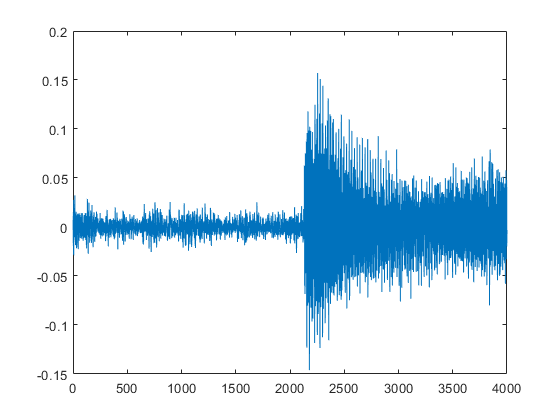

clc, clear

% [y,fs]=audioread("5.mp3");
%  
% sound(y,fs)

fs = 2000;
recObj = audiorecorder(fs, 16, 1);
recordblocking(recObj, 2);
y = getaudiodata(recObj);

plot(y)

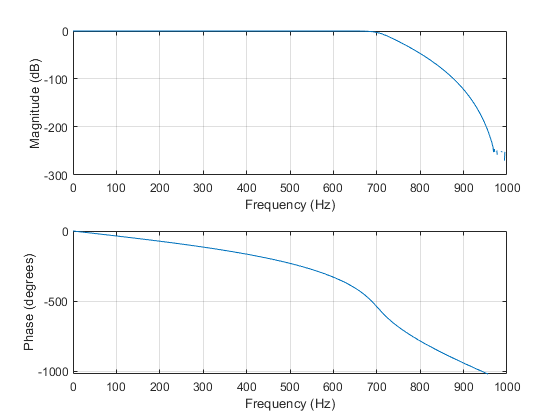


dp = 2;
f = 700;
Wp= f/(fs/2);
[b, a] = butter(12,Wp,"low");
freqz(b,a,1024, fs)

y1= filter(b,a,y);

g=fft(y1);
potencia=abs(g).^2;
df=1/(length(y)/fs);
f=(0:length(y)-1)*df; 
[pks,locs]=findpeaks(potencia,"SortStr","descend","NPeaks",15);
fn0 = min(f(locs))

fn0 = 245.5000

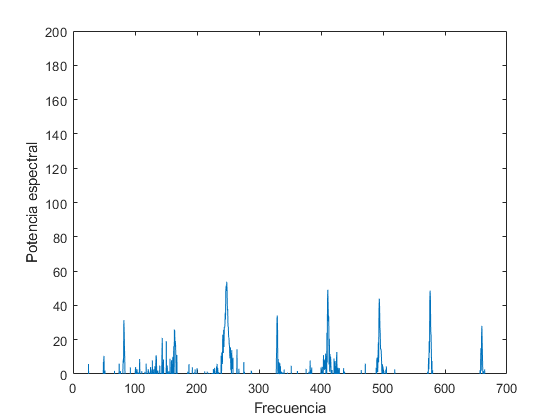



plot(f,20*log10(potencia))
axis([0 700 0 200])
xlabel('Frecuencia')
ylabel('Potencia espectral')

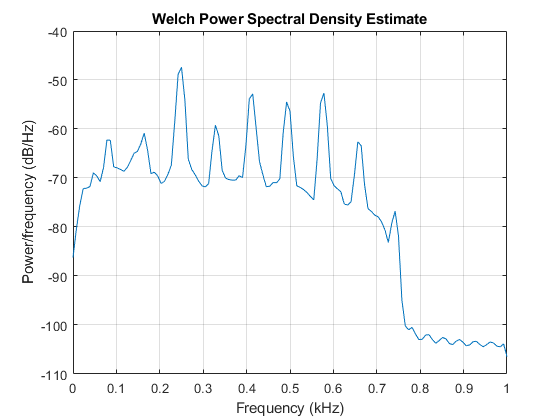


L = 0.1*fs;
overlap = floor(0.9*L);
nfft = 2^nextpow2(L);
[pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
pwelch(y1,hamming(L),overlap,nfft,fs)

[pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',15, 'MinPeakHeight',min(pxx)*25000);
sort(f(locs))

ans =    78.1250
  164.0625
  250.0000
  328.1250
  414.0625
  492.1875
  578.1250


fn1= min(f(locs))

fn1 = 78.1250